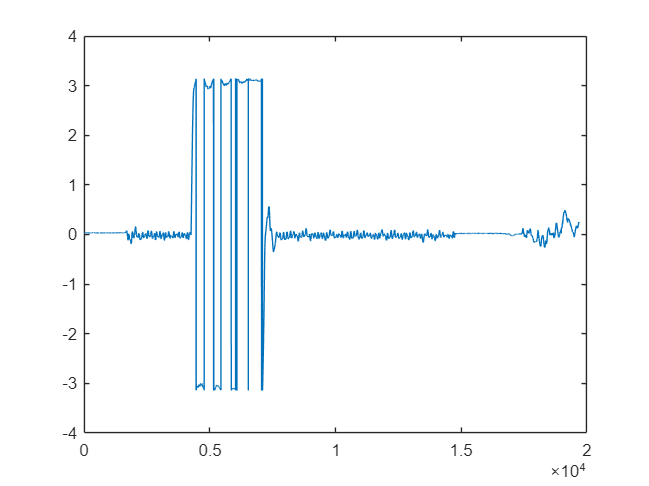

q = [quaternion_w, quaternion_x, quaternion_y, quaternion_z];
[pitch, roll, yaw] = quat2angle(q, 'YXZ');
plot(pitch)

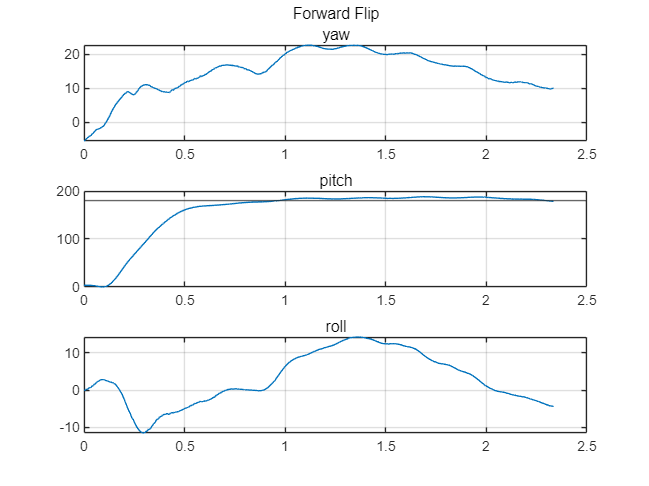

ff = 4289;
bf = 7156;
plot_euler(ff, pose_time, pitch, roll, yaw, 'positive', false)

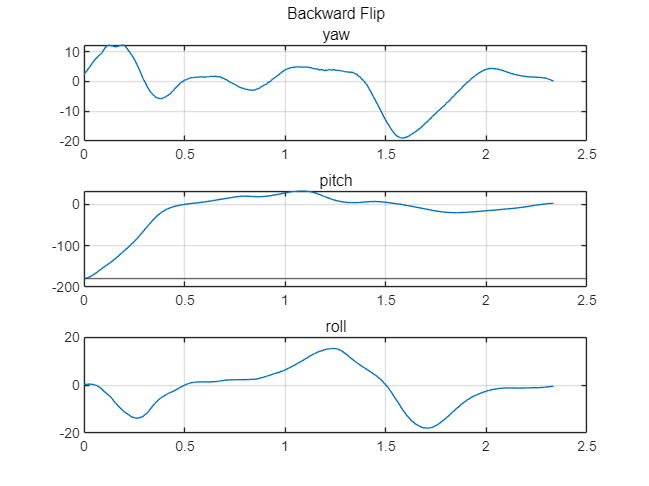

plot_euler(bf, pose_time, pitch, roll, yaw, 'negative', false)

function plot_euler(ff, pose_time, pitch, roll, yaw, compensate, onlypitch)
before = 60; after = 500;
plot_time = pose_time(ff-before:ff+after) - pose_time(ff-before);
plot_pitch = rad2deg(pitch(ff-before:ff+after));
plot_roll = rad2deg(roll(ff-before:ff+after));
plot_yaw = rad2deg(yaw(ff-before:ff+after));

if compensate == 'positive'
plot_pitch(find(plot_pitch<-100)) = plot_pitch(find(plot_pitch<-100)) + 2*180;
elseif compensate == 'negative'
plot_pitch(find(plot_pitch>100)) = plot_pitch(find(plot_pitch>100)) - 2*180;
end

if onlypitch == true
figure;
plot(plot_time, plot_pitch); subtitle('pitch'); grid on
if compensate == 'positive'
yline(180)
elseif compensate == 'negative'
yline(-180)
end
if compensate == 'positive'
title('Forward Flip')
elseif compensate == 'negative'
title('Backward Flip')
end
return
end

figure;
subplot(3,1,1); 
plot(plot_time, plot_yaw); subtitle('yaw'); grid on
if compensate == 'positive'
title('Forward Flip')
elseif compensate == 'negative'
title('Backward Flip')
end
subplot(3,1,2);
plot(plot_time, plot_pitch); subtitle('pitch'); grid on
if compensate == 'positive'
yline(180)
elseif compensate == 'negative'
yline(-180)
end
subplot(3,1,3)
plot(plot_time, plot_roll);subtitle('roll'); grid on
end